# Homework 8

Ross Smyth

## Problem 1

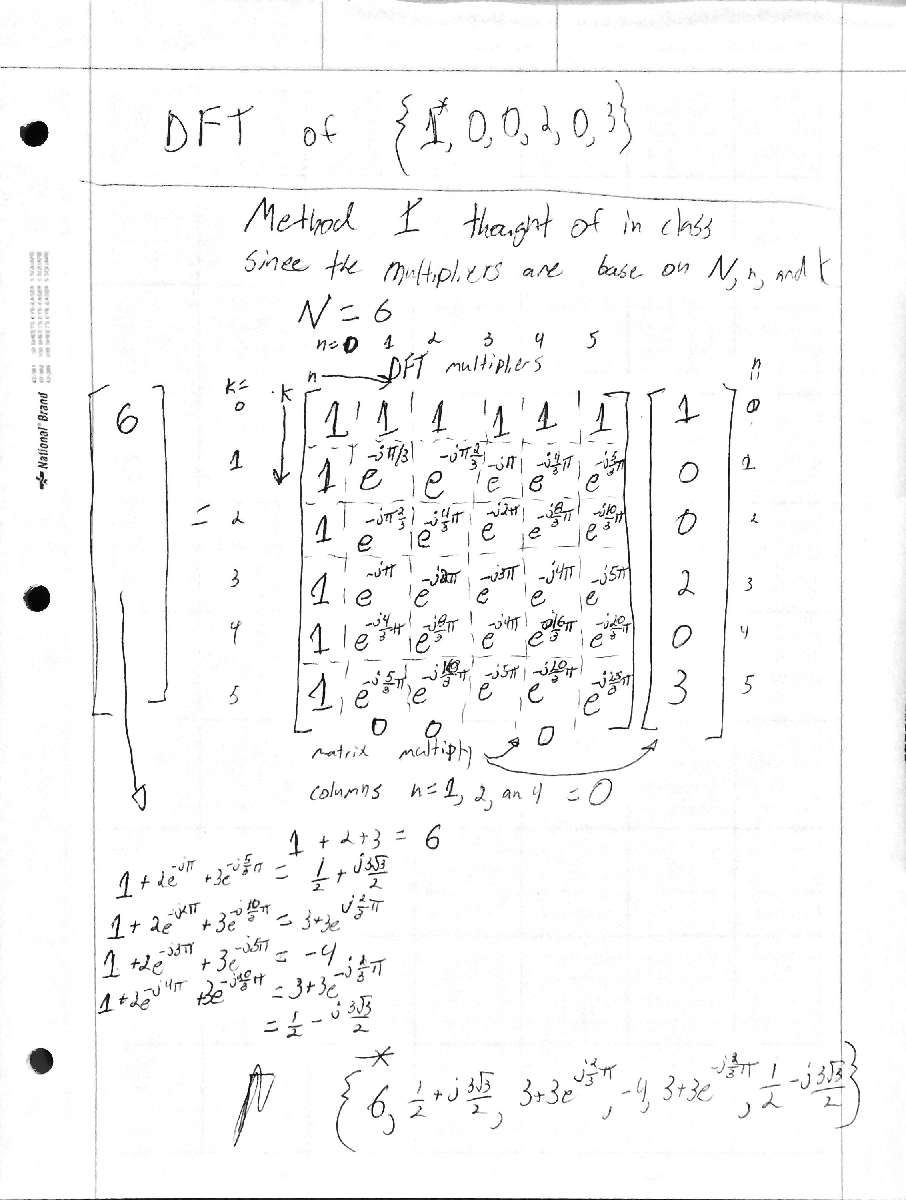

## Problem 2

clear, clc, close all

xn = [1, 0, 0, 2, 0, 3];

XF = fft(xn);

handwork = [6, 1/2 + 1i * 3 * sqrt(3)/2, 3 + 3*exp(1i * 2/3 * pi), -4, 3 + 3 * exp(-1i * 2/3 * pi), 1/2 - 1i * 3 * sqrt(3)/2];

valid = handwork == XF; % Not exact cause floating point/implementation error
handwork - XF % Very small error

ans = 	1.0e+-15 *

         0         0    0.6661         0    0.6661         0


## Problem 3

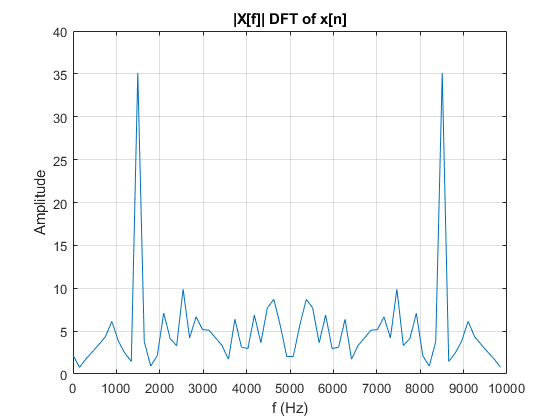

data = load('hw8.mat');

XF = fft(data.xn);

N = length(XF);
freq = (0:1/N:(N-1)/N) * data.S;

figure()
plot(freq, abs(XF))
xlabel('f (Hz)')
ylabel('Amplitude')
title('|X[f]| DFT of x[n]')
grid

[~, n] = max(XF); % will return first peak and not the conjugate. Probably.
max_f  = freq(n);

fprintf("Frequency of sinusoid is approximately: %0.0f Hz", max_f)

Frequency of sinusoid is approximately: 1493 Hz

## Problem 4

xn = randn(1, 1000)';

%% Mine
tic

N = length(xn);

mat = cumsum(ones(N, N)) - 1;
mat = exp(mat .* mat' * -1j * pi * 2 / N);
x_mine = mat * xn;

time_mine = toc;

%% MATLAB's
tic
x_fft = fft(xn);
time_fft = toc;

% Some error, probably from floating-point arithmetic.
validate = sum((abs(x_mine - x_fft)).^2);

% Can never reach it as the fft function is in C or FORTRAN.
multiplier = (time_mine - time_fft) / time_fft;

fprintf('My DFT time is: %g s\n', time_mine)

My DFT time is: 0.0405806 s


fprintf("MATLAB's DFT time is: %g s\n", time_fft)

MATLAB's DFT time is: 0.0044723 s


fprintf("MATLAB's DFT is %g times faster.\n", multiplier)

MATLAB's DFT is 8.07377 times faster.


fprintf("Note: This is way slower using MATLAB Live Script, which I am currently for this homework.\nWhen using MATLAB normally the builtin fft function is about 300 times faster.")

Note: This is way slower using MATLAB Live Script, which I am currently for this homework.
When using MATLAB normally the builtin fft function is about 300 times faster.